clear; % Clear any existing variables
close all;

% Get the path to the dataset and show first 5 samples
fpath = fullfile(pwd, 'wine-quality_Red.csv');                         % File path
fname = readtable(fpath, 'VariableNamingRule', 'preserve');      % Correct read file
firstFive = head(fname, 5);                                       % Display first 5 rows
verticalView = array2table(firstFive.Variables', ...
    'VariableNames', strcat("Sample", string(1:5)), ...
    'RowNames', fname.Properties.VariableNames);
disp(verticalView);

                            Sample1    Sample2    Sample3    Sample4    Sample5
                            _______    _______    _______    _______    _______

    fixed acidity              7.4        7.8        7.8       11.2        7.4 
    volatile acidity           0.7       0.88       0.76       0.28        0.7 
    citric acid                  0          0       0.04       0.56          0 
    residual sugar             1.9        2.6        2.3        1.9        1.9 
    chlorides                0.076      0.098      0.092      0.075      0.076 
    free sulfur dioxide         11         25         15         17         11 
    total sulfur dioxide        34         67         54         60   


% Check if all columns are numeric
nonNumericCols = varfun(@isnumeric, fname);     % Check each column
nonNumericColsNames = fname.Properties.VariableNames(~all(nonNumericCols{:, :}, 1));
if ~isempty(nonNumericColsNames)                % Check for non-numeric columns
    disp('Database is non-numeric.');
    disp(nonNumericColsNames);
else
    disp('Each column is numeric.');
end

Each column is numeric.



% Numeric summary
numericCols = varfun(@isnumeric, fname, 'OutputFormat', 'uniform');
numericData = fname(:, numericCols);
minVals = varfun(@min, numericData, 'OutputFormat', 'uniform');
maxVals = varfun(@max, numericData, 'OutputFormat', 'uniform');
summaryVertical = table(minVals', maxVals', 'VariableNames', {'Min', 'Max'}, 'RowNames', numericData.Properties.VariableNames);
disp(summaryVertical);

                              Min       Max  
                            _______    ______

    fixed acidity               4.6      15.9
    volatile acidity           0.12      1.58
    citric acid                   0         1
    residual sugar              0.9      15.5
    chlorides                 0.012     0.611
    free sulfur dioxide           1        72
    total sulfur dioxide          6       289
    density                 0.99007    1.0037
    pH                         2.74      4.01
    sulphates                  0.33         2
    alcohol                     8.4      14.9
    quality                       3         8




% Class Distribution
qualityCounts = countcats(categorical(fname.quality));
uniqueClasses = unique(fname.quality);
for i = 1:length(uniqueClasses)
    fprintf('Class %d has %d samples\n', uniqueClasses(i), qualityCounts(i));
end

Class 3 has 10 samples
Class 4 has 53 samples
Class 5 has 681 samples
Class 6 has 638 samples
Class 7 has 199 samples
Class 8 has 18 samples


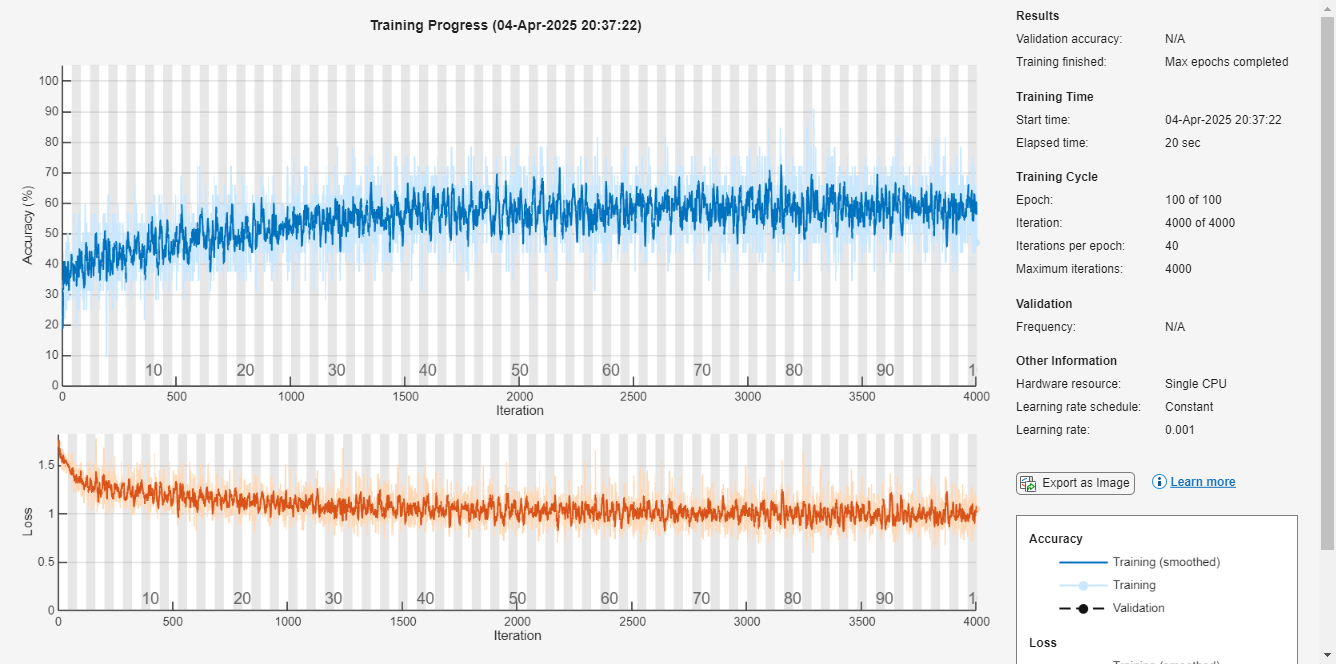


% Normalization of all data
X = fname{:, 1:11};                  % Features (first 11 columns)
Y = fname{:, 12};                    % Quality rating (12th column)
X = (X - min(X)) ./ (max(X) - min(X));  % Min-Max normalization

% Convert labels to categorical format
Y_categorical = categorical(Y); % Keep this as categorical for training

% Split the Data into Training and Test Sets
cv = cvpartition(size(X, 1), 'HoldOut', 0.2);
X_train = X(training(cv), :);
Y_train = Y_categorical(training(cv)); % Use categorical labels directly
X_test = X(test(cv), :);
Y_test = Y_categorical(test(cv)); % Use categorical labels directly

% Compute weight for class
classCounts = countcats(Y_categorical);
totalSamples = sum(classCounts);
classWeights = totalSamples ./ classCounts;  % Inverse frequency

% Normalize class weights to sum to 1
classWeights = classWeights / sum(classWeights);

% Create a layer graph
layers = [
    featureInputLayer(11)               % Input layer
    fullyConnectedLayer(12)              % Hidden layer
    dropoutLayer(0.5)                    % Dropout layer
    fullyConnectedLayer(numel(uniqueClasses)) % Output layer
    softmaxLayer                          % Softmax layer
    classificationLayer                  % Classification layer
];

lgraph = layerGraph(layers);

% Create and Train the Network
options = trainingOptions('adam', ...
    'MaxEpochs', 100, ...
    'Shuffle', 'every-epoch', ...
    'Verbose', false, ...
    'Plots', 'training-progress', ...
    'MiniBatchSize', 32); % Removed ClassWeights

% Train the network
net = trainNetwork(X_train, Y_train, lgraph, options); % Use Y_train as categorical


% Test the Network
Y_pred = classify(net, X_test);
Y_true_class = Y_test; % Use categorical labels directly

% Calculate Precision, Recall, F1-score
confMat = confusionmat(Y_true_class, Y_pred);
numClasses = size(confMat, 1);
precision = zeros(numClasses, 1);
recall = zeros(numClasses, 1);
f1 = zeros(numClasses, 1);

for i = 1:numClasses
    TP = confMat(i, i);
    FP = sum(confMat(:, i)) - TP;
    FN = sum(confMat(i, :)) - TP;
    precision(i) = TP / (TP + FP + eps);
    recall(i) = TP / (TP + FN + eps);
    f1(i) = 2 * (precision(i) * recall(i)) / (precision(i) + recall(i) + eps);
end

disp('Class | Precision | Recall | F1-score');

Class | Precision | Recall | F1-score


for i = 1:numClasses
    fprintf('  %2d   |   %.2f    | %.2f   |  %.2f\n', i, precision(i), recall(i), f1(i));
end

   1   |   0.00    | 0.00   |  0.00
   2   |   0.00    | 0.00   |  0.00
   3   |   0.62    | 0.74   |  0.68
   4   |   0.53    | 0.57   |  0.55
   5   |   0.50    | 0.21   |  0.30
   6   |   0.00    | 0.00   |  0.00



macroPrecision = mean(precision);
macroRecall = mean(recall);
macroF1 = mean(f1);

fprintf('\nMacro-avg Precision: %.2f\n', macroPrecision);


Macro-avg Precision: 0.27


fprintf('Macro-avg Recall: %.2f\n', macroRecall);

Macro-avg Recall: 0.25


fprintf('Macro-avg F1-score: %.2f\n', macroF1);

Macro-avg F1-score: 0.25



% Evaluation of classification quality
accuracy = sum(Y_pred == Y_true_class) / length(Y_true_class);
fprintf('Accuracy: %.2f%%\n', accuracy * 100);

Accuracy: 57.37%


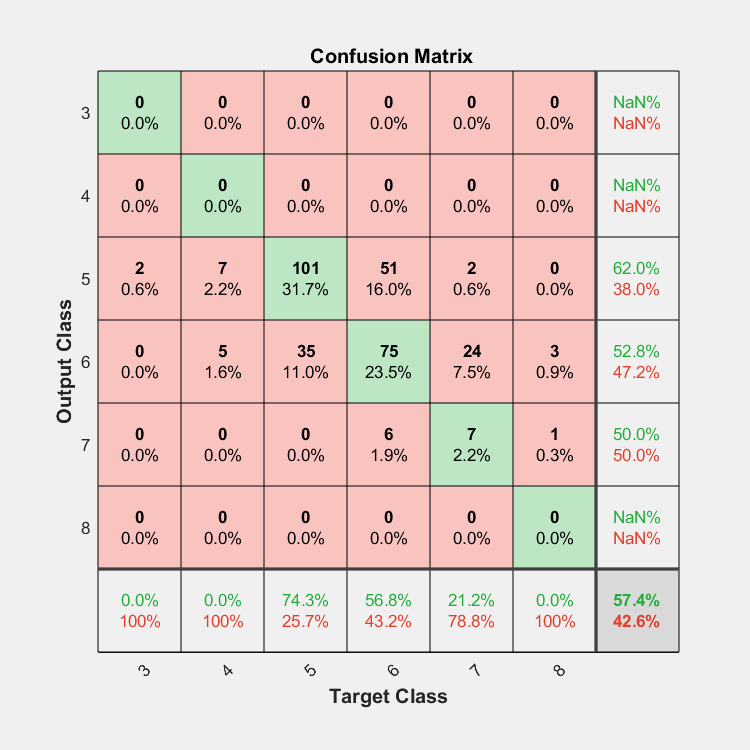


% Confusion Matrix
figure;
plotconfusion(Y_test, Y_pred);

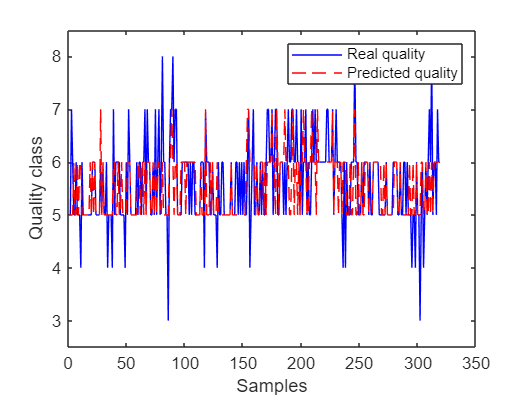

% Comparison of actual and predicted classes
figure;
plot(Y_true_class, 'b'); hold on;
plot(Y_pred, 'r--');
legend('Real quality', 'Predicted quality');
xlabel('Samples');
ylabel('Quality class');